Reset

clear

Open DSD

% drivingScenarioDesigner("testingTrack/kidneyBeanTest.mat");

Initialize bKin & driving scenario

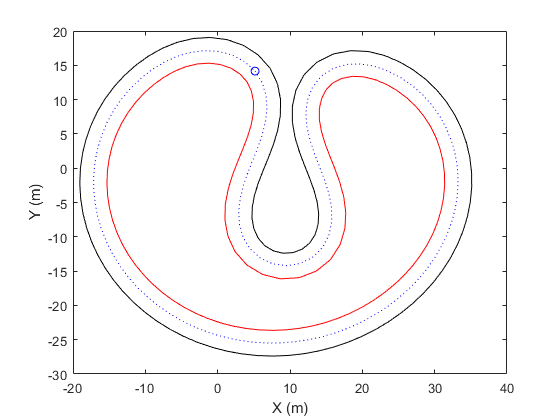

clear 

scenario = kidneyBeanTest;
bicycle = actor(scenario,'ClassID',3,'Position',[5.166 14.157 0]','Length',1.5,'Width',0.45,'Yaw',-50);
bounds = roadBoundaries(scenario);
outerBounds = bounds{1};
outerBounds = flip(outerBounds(:,1:2),1);
innerBounds = bounds{2}(:,1:2);
centers = horzcat(mean([innerBounds(:,1), outerBounds(:,1)],2),mean([innerBounds(:,2), outerBounds(:,2)],2));
centersDiff = [0; sum((centers(2:end,:)-centers(1:end-1,:)).^2,2)];
sVals = cumsum(centersDiff);
inXHighRes = interp1(sVals', innerBounds(:,1),0:0.5:max(sVals))';
inYHighRes = interp1(sVals',innerBounds(:,2),0:0.5:max(sVals))';
outXHighRes = interp1(sVals', outerBounds(:,1),0:0.5:max(sVals))';
outYHighRes = interp1(sVals', outerBounds(:,2),0:0.5:max(sVals))';
inHighRes = [inXHighRes, inYHighRes];
outHighRes = [outXHighRes, outYHighRes];
cenHighRes = horzcat(mean([inHighRes(:,1), outHighRes(:,1)],2),mean([inHighRes(:,2), outHighRes(:,2)],2));
clear innerBounds outerBounds centersDiff centers bounds

plot(outHighRes(:,1),outHighRes(:,2),'k')
hold on
plot(inHighRes(:,1),inHighRes(:,2),'r')
plot(cenHighRes(:,1),cenHighRes(:,2),':b')
plot(5.166,14.157,'ob')
xlabel("X (m)")
ylabel("Y (m)")
hold off

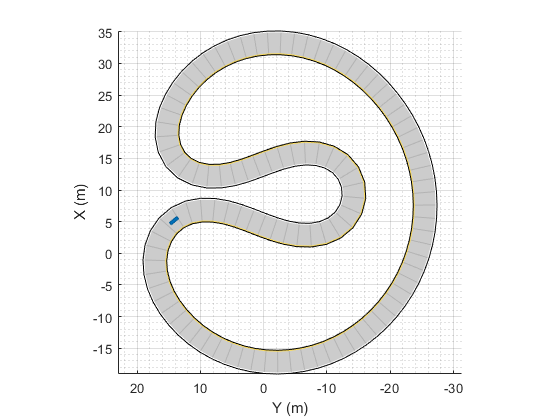

% I need a way to generate a list of waypoints and speeds accomodating for
% acceleration limitations. If we use 0.05 second steps, x = x0 + dT*vx

% [t,y] = ode45(@(t,y)derivative(bikeInstance,y,[5,pi/6]),0:0.05:2,bIInitial);
% plot(y(:,1),y(:,2))

forwardVectorInit = 2.5*[cosd(-50), sind(-50)];

plot(scenario)
hold on

plot(centers(1:31,1),centers(1:31,2))

Unrecognized function or variable 'centers'.

hold off
% while advance(scenario)
%     pause(scenario.SampleTime)
% end